%https://www.mathworks.com/content/dam/mathworks/tag-team/Objects/c/88360_93001v00_Color-Based_Seg_K-Means_Clustering_2016.pdf

addpath('databas')
database = cell(1,200);

for i = 1:size(database,2)
    fileName = strcat(int2str(i),'.jpg');
    img = im2double(imread(fileName));
    database{i} = img;
end

allChannels = zeros(3,200)

allChannels =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i = 1:200
    
    fileName = strcat(int2str(i),'.jpg');
    img = im2double(imread(fileName));
    allChannels(1,i) = mean(mean(img(:, :, 1)));
    allChannels(2,i) = mean(mean(img(:, :, 2)));
    allChannels(3,i) = mean(mean(img(:, :, 3)));
end
X = allChannels';
idx = kmeans(X,3)

idx =      3
     2
     3
     1
     3
     1
     1
     3
     2
     3


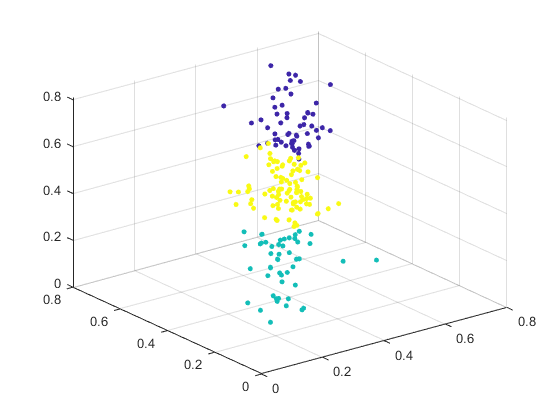


scatter3(X(:,1),X(:,2),X(:,3),15,idx,'filled')